# Find Frequency Spikes

Instructions are in the task pane to the left. Complete and submit each task one at a time.

This code sets up the activity.

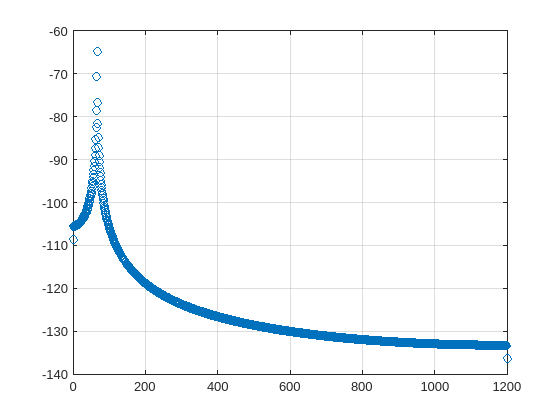

load ./data/psdsig.mat
sig = 1e-3*sin(2*pi*fr*t);
n = length(sig);
[p, f] = periodogram(sig, ones(n, 1), n*1, fs);
pwr = 10*log10(p);
plot(f, pwr, "o")
grid on

## Task 1

The goal of spectral analysis is often to accurately find the frequency content in a signal. In this module, you will use the `findpeaks` function to locate the frequency spikes.

`[``p``,``lo``]` `=` `findpeaks``(``sig``,``loc``,``"NPeaks"``,``n``,``...`

`"SortStr"``,``"descend"``)`

By default, `findpeaks` returns the peaks in the order in which they occur. To return the most prominent peak, you can set the peak sorting to `"descend"`.

[peak, loc] = findpeaks(pwr, f, "NPeaks", 1, "SortStr", "descend")

peak = -64.6742

loc = 67

## Task 2

The correct frequency in the signal is the fan's rotating frequency of 4000 rotations per minute (rpm). To convert from rpm to Hz, or cycles per second, divide by 60. This is stored in the variable `fr`.

In the periodogram, the peak should be located at `fr`. You can use the peak found by `findpeaks` to check if the peak was found precisely.

There are many ways to calculate error. For this task, you can use `abs``(``a``-``b``)`.

e = abs(fr - loc)

e = 0.3333